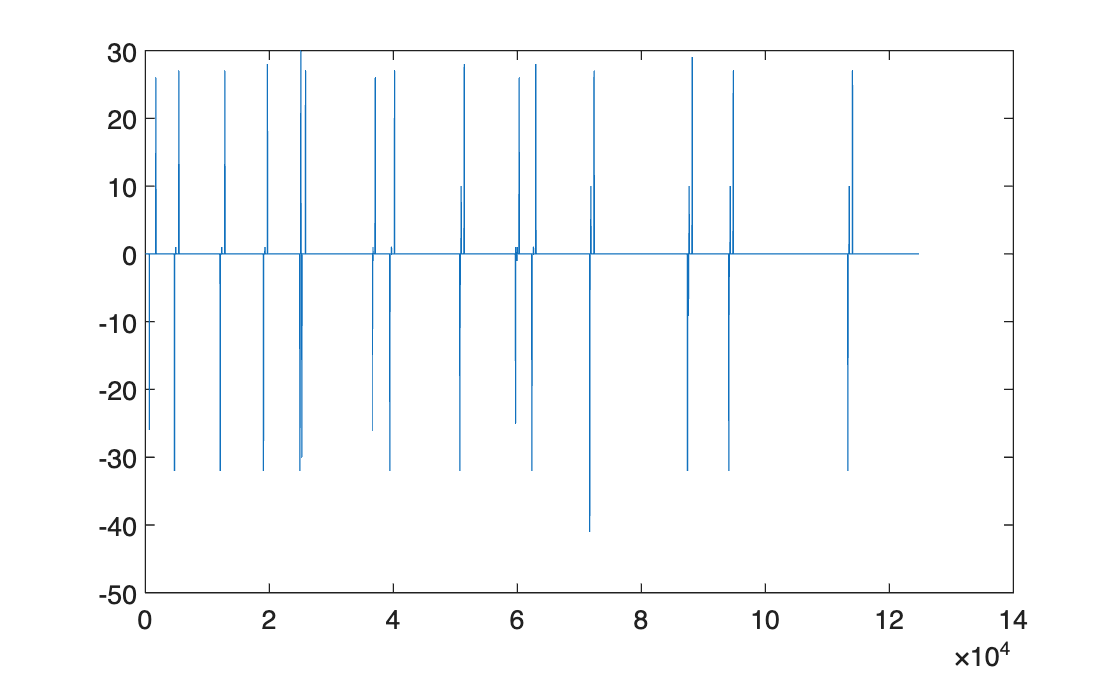

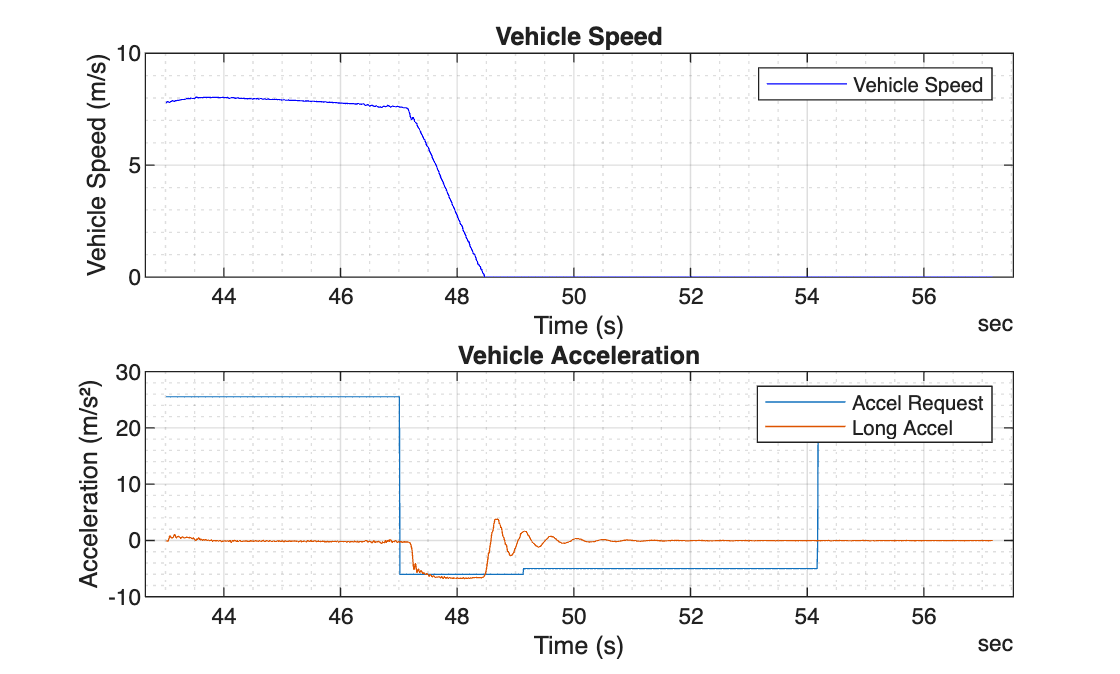

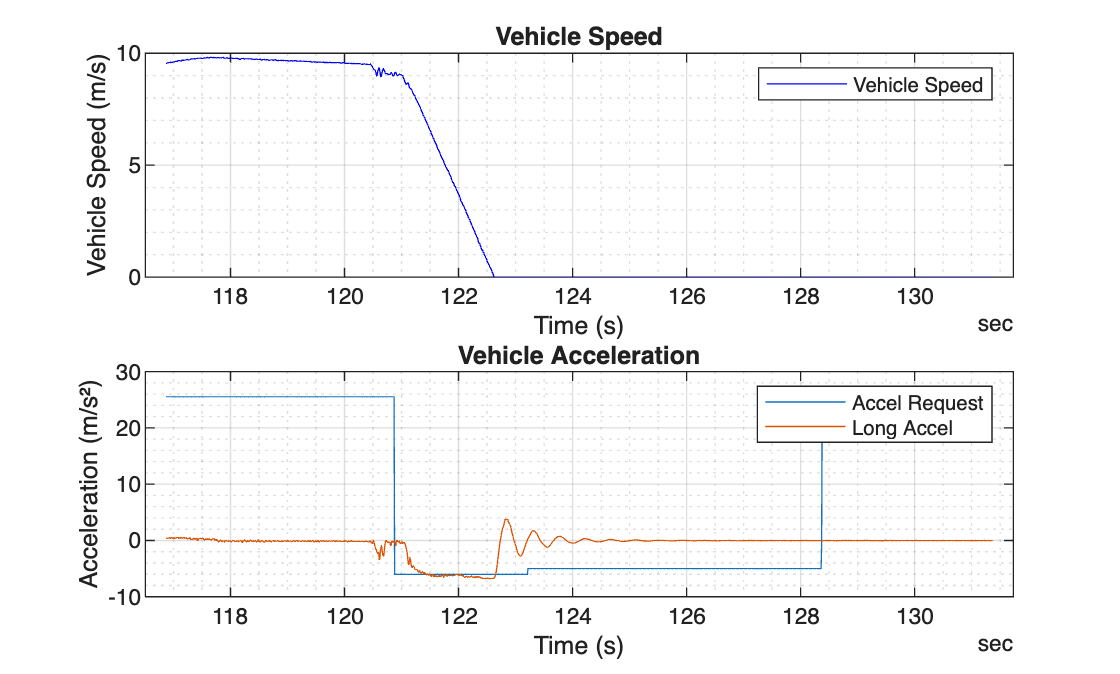

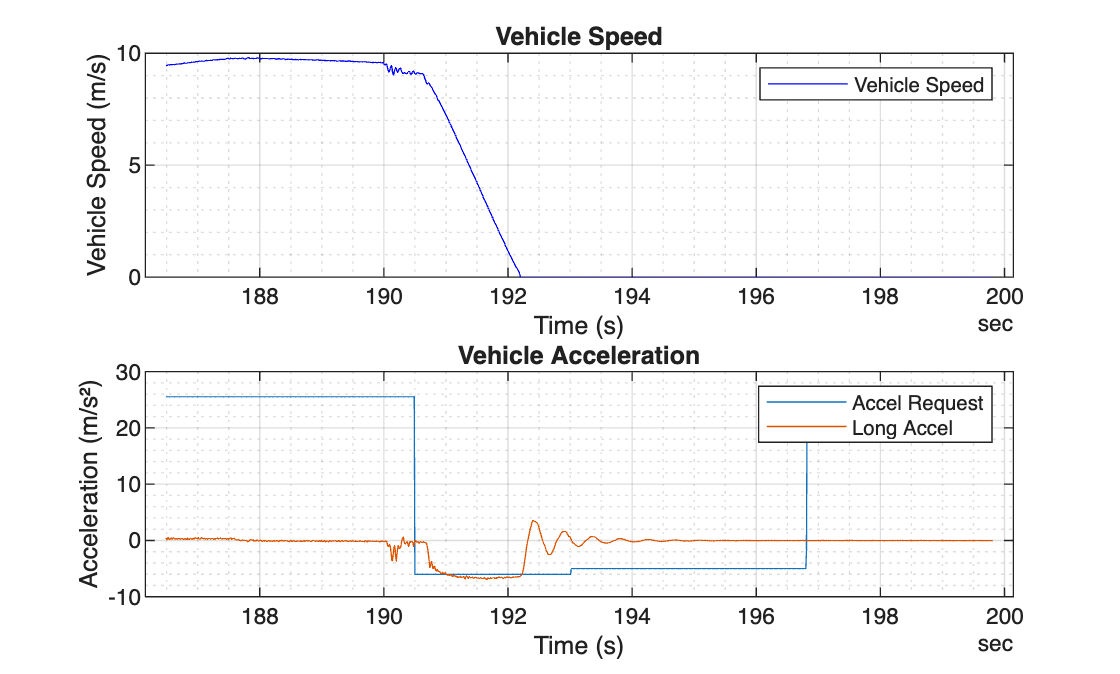

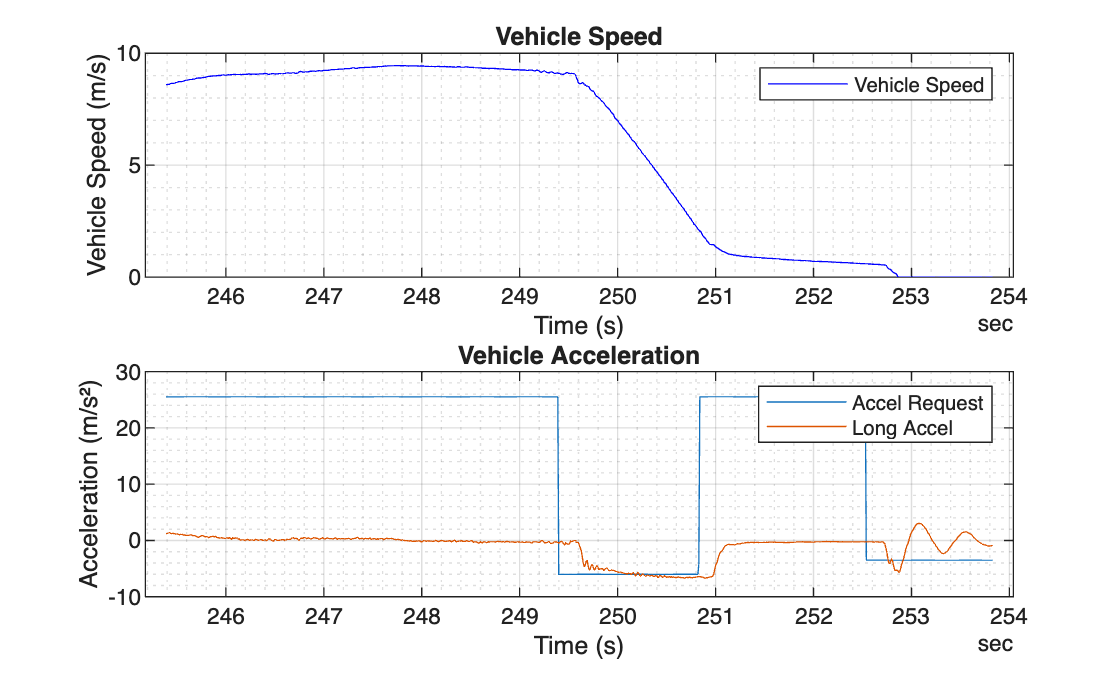

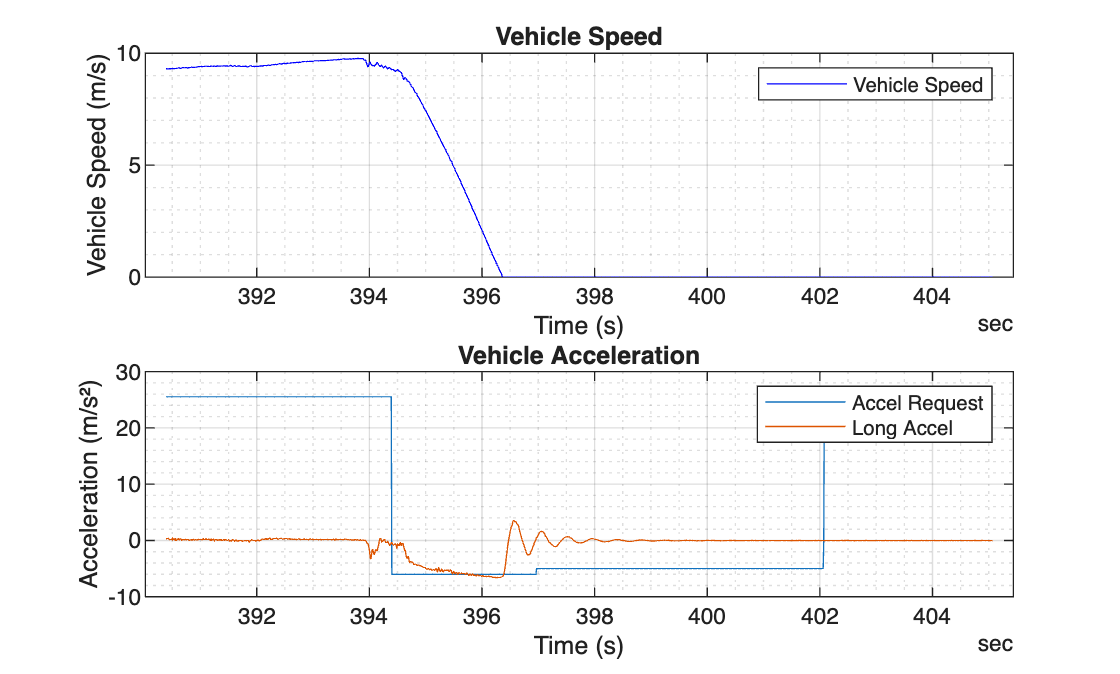

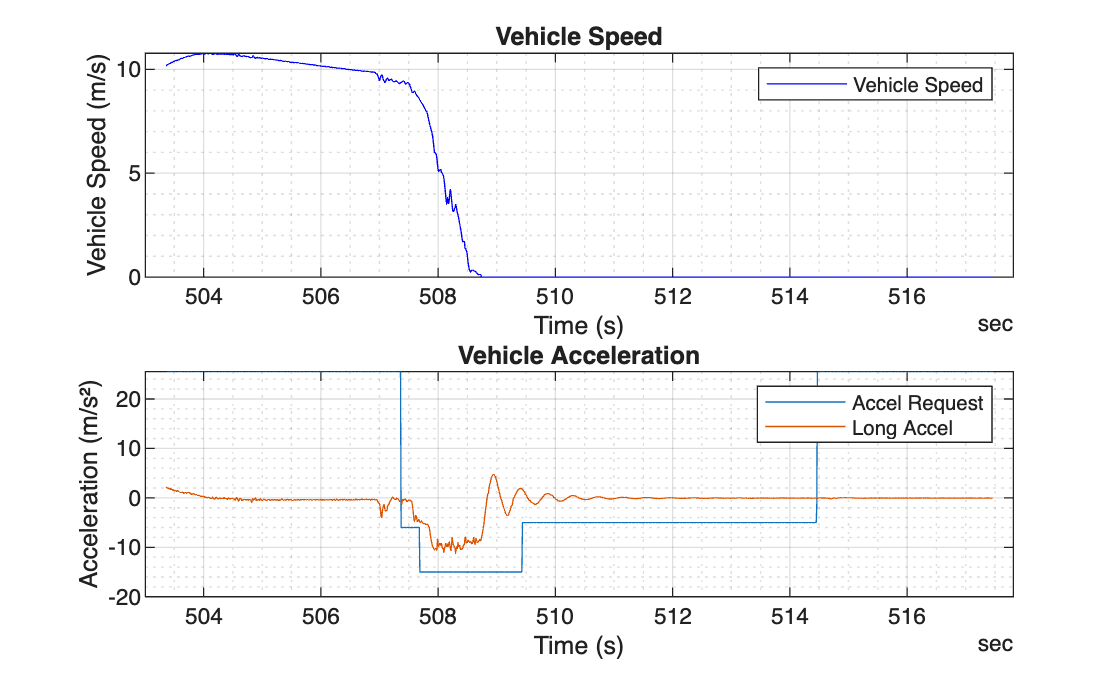

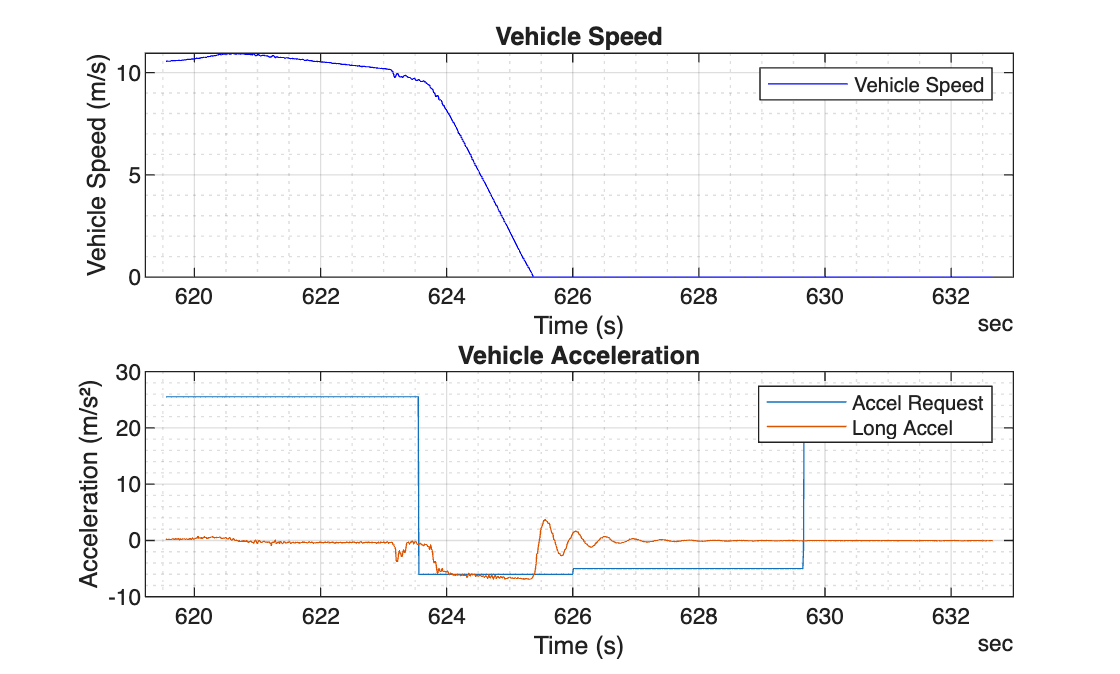

cur_folder = pwd;
seldatapath = uigetdir(cur_folder,'Select folder with *.mat files');
dest_folder = seldatapath;
cd(dest_folder)
mkdir 'PostProcessing'
cd (seldatapath);
files = dir('*.mat');   % get all *.dat files of the present folder
N = length(files) ;

for i = 1:N
    filePath = fullfile(files(i).folder, files(i).name);
    [seldatapath,name,ext] = fileparts(filePath);
    
    MatFileFullName = fullfile(dest_folder,[name '.mat']);
    save(MatFileFullName,"signalMat");
    
     AEB_Split_v3_V01
end

cd (cur_folder);